# Database for Upper and Lower Limb Task Based on EEG Signals During the Execution of Motor and Motorimagery Tasks

Víctor Asanza, Daniel Montoya, Enrique Peláez, Francis Loayza, Leandro L. Lorente-Leyva, Diego H. Peluffo-Ordóñez and Kleber Gonzalez

- Main Code: [https://github.com/vasanza/BCI_Motor_Imagery_Task_OpenBCI.git](https://github.com/vasanza/BCI_Motor_Imagery_Task_OpenBCI.git)

- `Data Mendeley: `[http://dx.doi.org/10.17632/w9xfz56txv.1](http://dx.doi.org/10.17632/w9xfz56txv.1)

- `More Matlab Examples: `[https://github.com/Human-Machine-Interface](https://github.com/Human-Machine-Interface)

- Hardware: FM=16 chanels , Cyton + Dasy , Campling Rate = 125 Hz

- Subjects: 24

# Prepare the raw dataset

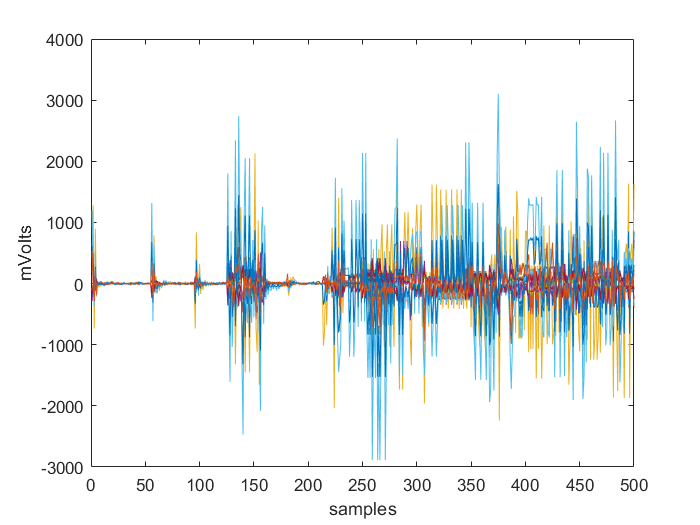

Conversion to matlab.graphics.chart.primitive.Line from cell is not possible.

Error in saveas (line 77)
                h(n) = hP;

Error in fPlotEEG (line 16)
	savefig(strcat(filename,'.fig))

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
path = fullfile('./data/');%data folder
folders = FindFolders(path);
allData=[];

for i=1:length(folders)% Through all folders
    path1=fullfile(path,folders(i).name);%Select i folder
    filenames = FindCSV(path1);%List All CSV files
    for j=1:length(filenames)% Through all files
        data=readtable(fullfile(path1,filenames(j).name));%Select i CSV file
        dataNew=table2array(data);% Array Double
        dataNew(1,:)=[];%Delete the first row
        dataNew(:,1)=[];%Delete the first column
        DataNorm = fNormalization(dataNew);
        DataRMS = [rms(DataNorm) fLabelEEG(filenames(j).name)];
        allData=[allData;DataRMS];
        
        filename=strcat('./figures/',strcat(int2str(i),'_',int2str(j)));
        fPlotEEG(dataNew,filename);
    end
end

# Test Motor Task (Label + 8)

Some Best Results: 

- **5) Left Upper limbs task, SVM (Medium Gaussian VM) 78%**

- 7) Right Lower limbs task Dorsal, Ensemble (Subspace KNN) 74%

- 8) Right Lower limbs task Plantar, SVM (Quadratic) 76.7%

- 10) Left Lower limbs task Dorsal, SVM (Quadratic SVM) 76%

- **11) Left Lower limbs task Plantar, Ensemble (Subspace KNN) 77%**

%[ILCH, IRCH, ILDF, ILPF, IRDF, IRPF, IDesc, idxMaxI] = fIdxLabelEEG_I(allData);
[MLCH, MRCH, MLDF, MLPF, MRDF, MRPF, MDesc, idxMaxM] = fIdxLabelEEG_M(allData);

num = input('Enter a number: ');
switch num
    case 1 %all task
        idx = [MLCH(1:idxMaxM);MRCH(1:idxMaxM);MLDF(1:idxMaxM);MLPF(1:idxMaxM);...
            MRDF(1:idxMaxM);MRPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('All task')%-->KNN(Coarse KNN) 23.8%
    case 2 %upper limbs task
        idx = [MLCH(1:idxMaxM);MRCH(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Upper Limbs task')%--> KNN(Weighted KNN) 50.7%
    case 3 %Lower limbs task
        idx = [MLDF(1:idxMaxM);MLPF(1:idxMaxM);MRDF(1:idxMaxM);MRPF(1:idxMaxM);...
            MDesc(1:idxMaxM)];
        disp('Lower Limbs task')%--> Ensemble (Boosted Trees) 31.5%
    case 4 %Right Upper limbs task
        idx = [MRCH(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Upper limbs task')%--> Tree (fine Tree, medium tree) 70.7%
    case 5 %Left Upper limbs task
        idx = [MLCH(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Upper limbs task')%--> SVM (Medium Gaussian VM) 78%
    case 6 %Right Lower limbs task
        idx = [MRDF(1:idxMaxM);MRPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Lower limbs task')%--> Ensemble (Subspace KNN, RUSBoosted KNN) 51.6%
    case 7 %Right Lower limbs task Dorsal
        idx = [MRDF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Lower limbs task Dorsal')%--> Ensemble (Subspace KNN) 74%
    case 8 %Right Lower limbs task Plantar
        idx = [MRPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Lower limbs task Plantar')%--> SVM (Quadratic) 76.7%
    case 9 %Left Lower limbs task
        idx = [MLDF(1:idxMaxM);MLPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Lower limbs task')%-->  KNN (Weighted) 53.8%
    case 10 %Left Lower limbs task Dorsal
        idx = [MLDF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Lower limbs task Dorsal')%--> SVM (Quadratic SVM) 76%
    case 11 %Left Lower limbs task Plantar
        idx = [MLPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Lower limbs task Plantar')%--> Ensemble (Subspace KNN) 77%
    otherwise
        disp('other value')
end

MotorData=allData(idx,:);

# Test Imagery Task (Label)

Some Best Results: 

- 4) Right Upper limbs task, KNN (Weighted KNN) 71.3%

- 7) Right Lower limbs task Dorsal, Ensemble (Subspace KNN) 70.7%

- **8) Right Lower limbs task Plantar, Ensemble (Subspace KNN) 78%**

[ILCH, IRCH, ILDF, ILPF, IRDF, IRPF, IDesc, idxMaxI] = fIdxLabelEEG_I(allData);
%[MLCH, MRCH, MLDF, MLPF, MRDF, MRPF, MDesc, idxMaxM] = fIdxLabelEEG_M(allData);

num = input('Enter a number: ');
switch num
    case 1%all task
        idx = [ILCH(1:idxMaxI);IRCH(1:idxMaxI);ILDF(1:idxMaxI);ILPF(1:idxMaxI);...
            IRDF(1:idxMaxI);IRPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('All task')%--> KNN (Weighted KNN) 21.9%
    case 2%upper limbs task
        idx = [ILCH(1:idxMaxI);IRCH(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Upper Limbs task')%--> Ensemble (Boosted Trees) 47.6%
    case 3%Lower limbs task
        idx = [ILDF(1:idxMaxI);ILPF(1:idxMaxI);IRDF(1:idxMaxI);IRPF(1:idxMaxI);...
            IDesc(1:idxMaxI)];
        disp('Lower Limbs task')%--> Ensemble (Suspace KNN) 30.1%
    case 4 %Right Upper limbs task
        idx = [IRCH(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Upper limbs task')%--> KNN (Weighted KNN) 71.3%
    case 5 %Left Upper limbs task
        idx = [ILCH(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Upper limbs task')%--> Ensemble (Bagged Trees) 66.7%
    case 6 %Right Lower limbs task
        idx = [IRDF(1:idxMaxI);IRPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Lower limbs task')%--> Ensemble (Subspace KNN) 48.4%
    case 7 %Right Lower limbs task Dorsal
        idx = [IRDF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Lower limbs task Dorsal')%--> Ensemble (Subspace KNN) 70.7%
    case 8 %Right Lower limbs task Plantar
        idx = [IRPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Lower limbs task Plantar')%--> Ensemble (Subspace KNN) 78%
    case 9 %Left Lower limbs task
        idx = [ILDF(1:idxMaxI);ILPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Lower limbs task')%--> Naiveyes (Gaussian Naive yes) 47.6%
    case 10 %Left Lower limbs task Dorsal
        idx = [ILDF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Lower limbs task Dorsal')%--> Quadratic (Quadratic Discriminant) 68%
    case 11 %Left Lower limbs task Plantar
        idx = [ILPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Lower limbs task Plantar')%--> Ensemble (Bagged Trees) 68%
    otherwise
        disp('other value')
end

ImageryData=allData(idx,:);

# Plot Raw Data (Dataset)

figure
plot(DataNorm);xlabel('samples');ylabel('mVolts');
legend('Electrode 1','Electrode 2','Electrode 3','Electrode 4','Electrode 5'...
    ,'Electrode 6','Electrode 7','Electrode 8','Electrode 9','Electrode 10'...
    ,'Electrode 11','Electrode 12','Electrode 13','Electrode 14','Electrode 15','Electrode 16');

# Plot Raw Data (Dataset)

figure
plot(dataNew);xlabel('samples');ylabel('value');
legend('Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','RAM Consumption (%)');

# Statital Information Raw Data (Dataset)

xds_v = datastats(dataNew(:,1))%Voltage (V)
xds_C = datastats(dataNew(:,2))%Current (A)
xds_AP = datastats(dataNew(:,3))%Active Power (W)
xds_F = datastats(dataNew(:,4))%Frecuency (Hz)
xds_AE = datastats(dataNew(:,5))%Active Energy (KWh)
xds_PF = datastats(dataNew(:,6))%Power Factor
xds_T = datastats(dataNew(:,7))%ESP32 Temperature (°C)
xds_CPU = datastats(dataNew(:,8))%CPU Consumption (%)
xds_RAM = datastats(dataNew(:,9))%RAM Consumption (%)

# 1 - Preprocessing (Normalization)

DataNorm=[];
DataNorm=fNormalization(dataNew);

# Plot Normalization Data (Dataset)

figure
plot(DataNorm);xlabel('samples');ylabel('value');
legend('Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','RAM Consumption (%)');

# 2 - Feature Extraction (rms by temporary window)

% Select only one TimeStep
% not enough data... TimeStep =2592000;% one month in second
%TimeStep =604800;% one week in second (only 2 weeks)
TimeStep =86400;% one day in second (ok)
%TimeStep =3600;% one hour in second (ok)
%TimeStep =60;% one minute in second (ok)
%TimeStep =1;% one second

DataFeatures = frms_features(DataNorm,TimeStep);

% Feature 1: rms(Active Power (W))
xds_F1 = datastats(DataFeatures(:,1))
% Feature 2: rms(Active Energy (KWh))
xds_F2 = datastats(DataFeatures(:,2))
% Feature 3: rms(CPU Consumption (%))
xds_F3 = datastats(DataFeatures(:,3))
% Feature 4: rms(RAM Consumption (%))
xds_F4 = datastats(DataFeatures(:,4))

# 3 - Feature Selection

%corrplot(DataNorm)
R = corrcoef(DataFeatures)
%'Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','RAM Consumption (%)'
%Heat map
% Experimento: ESP32 Temperature
DataFeatures(:,7)=[];
% Based on corrcoef To delete: 
% PowerFactor -> alta correlacion con Active Energy (85%), entonces nos
% quedamos con Active Energy
% Voltage, current -> Alta correlacion con Active Power (91% y 86%),
% entonces nos quedfamos Active Power
DataFeatures(:,6)=[];DataFeatures(:,2)=[];DataFeatures(:,1)=[];
% Parametros electricos: Frecuency
DataFeatures(:,2)=[];
%Nos quedamos con estas variables: 'Active Power (W)','Active Energy (KWh)','CPU Consumption (%)','RAM Consumption (%)'

# 4 - Regression Learner (Input output Data)

training=0.85; %70 Training, 15% Validation, 15% Testing
testing=0.15;

input=[];output=[];
% inputs: Active Power (W),Active Energy (KWh),CPU Consumption (%),RAM Consumption (%)
input=DataFeatures(1:round(length(DataFeatures)*training)-1,:);
% output: Energía in the following time step
output=DataFeatures(1+1:round(length(DataFeatures)*training),2);
Samples=length(DataFeatures)*0.85-1

# RMSE (Testing): 1 day   

% inputs: Active Power (W),Active Energy (KWh),CPU Consumption (%),RAM Consumption (%)
TimeStep =86400;% one day in second (ok)
DataFeatures = frms_features(DataNorm,TimeStep);
DataFeatures(:,7)=[];DataFeatures(:,6)=[];DataFeatures(:,2)=[];DataFeatures(:,1)=[];DataFeatures(:,2)=[];

input_testing=DataFeatures(round(length(DataFeatures)*training):length(DataFeatures)-1,:);
% output: Energía in the following time step
output_testing=DataFeatures(round(length(DataFeatures)*training)+1:length(DataFeatures),2);

% To make predictions on a new predictor column matrix, X, use:
% yfit = c.predictFcn(X)
% replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'.
% X must contain exactly 4 columns because this model was trained using 4 predictors.
% X must contain only predictor columns in exactly the same order and format as your training data.
% Do not include the response column or any columns you did not import into the app. 

trainedModel_1day=load('trainedModel_1day.mat');%Load Best Prediction Model by 1day
predictValue_1day=trainedModel_1day.trainedModel_1day.predictFcn(input_testing);
% Denormilize Data
DpredictValue_1day=fDenormalize(predictValue_1day,xds_AE.max,xds_AE.min);
Doutput_testing=fDenormalize(output_testing,xds_AE.max,xds_AE.min);
[rmse_1day,mse_1day,mae_1day]=fBar_RmseMseMae(DpredictValue_1day,Doutput_testing);
figure
plot([DpredictValue_1day,Doutput_testing]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 day of prediction');

# RMSE (Testing): 1 hour

TimeStep =3600;% one hour in second (ok)
DataFeatures = frms_features(DataNorm,TimeStep);
DataFeatures(:,7)=[];DataFeatures(:,6)=[];DataFeatures(:,2)=[];DataFeatures(:,1)=[];DataFeatures(:,2)=[];

input_testing=DataFeatures(round(length(DataFeatures)*training):length(DataFeatures)-1,:);
% output: Energía in the following time step
output_testing=DataFeatures(round(length(DataFeatures)*training)+1:length(DataFeatures),2);

trainedModel_1hour=load('trainedModel_1hour.mat');%Load Best Prediction Model by 1hour
predictValue_1hour=trainedModel_1hour.trainedModel_1hour.predictFcn(input_testing);
% Denormilize Data
DpredictValue_1hour=fDenormalize(predictValue_1hour,xds_AE.max,xds_AE.min);
Doutput_testing=fDenormalize(output_testing,xds_AE.max,xds_AE.min);
[rmse_1hour,mse_1hour,mae_1hour]=fBar_RmseMseMae(DpredictValue_1hour,Doutput_testing);
figure
plot([DpredictValue_1hour,Doutput_testing]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 hour of prediction');

# RMSE (Testing): minute

TimeStep =60;% one minute in second (ok)
DataFeatures = frms_features(DataNorm,TimeStep);
DataFeatures(:,7)=[];DataFeatures(:,6)=[];DataFeatures(:,2)=[];DataFeatures(:,1)=[];DataFeatures(:,2)=[];

input_testing=DataFeatures(round(length(DataFeatures)*training):length(DataFeatures)-1,:);
% output: Energía in the following time step
output_testing=DataFeatures(round(length(DataFeatures)*training)+1:length(DataFeatures),2);

trainedModel_1min=load('trainedModel_1min.mat');%Load Best Prediction Model by 1min
predictValue_1min=trainedModel_1min.trainedModel_1min.predictFcn(input_testing);
% Denormilize Data
DpredictValue_1min=fDenormalize(predictValue_1min,xds_AE.max,xds_AE.min);
Doutput_testing=fDenormalize(output_testing,xds_AE.max,xds_AE.min);
[rmse_1min,mse_1min,mae_1min]=fBar_RmseMseMae(DpredictValue_1min,Doutput_testing);
figure
plot([DpredictValue_1min,Doutput_testing]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 minute of prediction');

# Summary RMSE (Testing): day, Hour and Min 

    c = categorical({'1Day','1Hour','1Min'});
    values = [rmse_1day rmse_1hour rmse_1min];
    figure;
    b=bar(c,values);
    ylabel('Error (KWh)')
    title('RMSE by TimeStep')
    xtips1 = b(1).XEndPoints - 0.2;
    ytips1 = b(1).YEndPoints + 0.0003;
    labels1 = string(b(1).YData);
    text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

# Data augmentation for temporal data

%New Testing adi


# FutureWork

%New Testing adicional...
% NOTA: hacer una prueba sin CPU Consumption (%),RAM Consumption (%) y ver
% si ayudan a mejorar la prediccion...